#    Нахождение параметров надежности по известным наработкам объекта

Мы заведомо знаем, что наработки до отказа подчиняются экспоненциальному закону. Полных наработок до отказа $\lambda =0\ldotp 01\;ч^{-1}$.

Плотность распределения экспоненциального закона $f\left(t\right)=\lambda \;e^{-\lambda \;t} \ldotp$

Пусть изначально на испытания поставлено N = 1000 работоспособных невосстанавливаемых объектов.

l = 0.01; % ИО 
N = 1000;

С помощью функции *exprand* найдем случайные точки экспоненциального распределения - *ksi* наработки (время).

ksi = exprnd(1/l, 1, N); 

Максимальная наработка:

max_ksi = max(ksi)

max_ksi = 732.5292

Рассмотрим интервалы $\Delta t=10\;ч\ldotp$

Далее на каждом интервале длиной $\Delta t$ будем считать количество наработок на каждом интервале - это будет число отказов *n:*

dt = 10;
n = zeros(1, round(max_ksi/dt));
interval = 0;
for i = 1:length(n)
    for j = 1:length(ksi)
        if and((ksi(j) > interval), (ksi(j) < interval + dt))
            n(i) = n(i) + 1;
        end
    end
    interval = interval + dt;
end

Пояснение алгоритма см. в приложении А.

**Зная количество отказов мы можем найти статистические оценки остальных параметров:**

Найдем плотность распределения $\overset{\wedge }{f\left(t\right)} =\frac{\Delta n\left(t-\frac{\Delta t}{2};t+\frac{\Delta t}{2}\right)}{\Delta t\bullet \textrm{N0}}$ и аппроксимируем ее полиномом 3-ей степени.

Задача: сравним получившиеся показатели качества с реальными данными об отказах (были заданы в ранней задаче) - статистика по отказам за 3000 ч на интервале 100 ч:

n_ex = [50 40 32 25 20 17 16 16 15 14 15 14 14 13 14 13 13 13 14 12 12 13 12 13 14 16 20 25 30 40];

Но т.к. в текущей задаче максимальная наработка равна

max_ksi = max(ksi)

max_ksi = 732.5292

то возьмем 

round(max_ksi/dt)

ans = 73

отказов.

t_ex = 1:100:round(max_ksi/100)*100;
n_ex = n_ex(1:round(max_ksi/100));
f = zeros(1, length(n));
f_ex = zeros(1, length(n_ex));
for i = 1:length(n)
    f(i) = n(i)/(N*dt);
end
for i = 1:length(n_ex)
    f_ex(i) = n_ex(i)/(N*100);
end
t = 1:dt:round(max_ksi/dt)*dt;
plot(t, f);

Аппроксимацию выполним, исходя из того, что вид получившейся плотности распределения соответствует экспоненциальному закону. Рассмотрим разность значений получившегося распределения и значиений плотности распределения с разными параметрами $\lambda$. И будем считать накапливаемую ошибку, а далее примем $\lambda$, при котором ошибка является минимальной за искомое.

За основу берется метод максимального правдоподобия.

error = 10000000;
sum_error1 = zeros(2001,2);
j = 0;
for lambda = -10:0.01:10
    j = j+1;
    f_app = lambda*exp(-lambda.*t);
    for i = 1:length(n)
        sum_error1(j,1) = sum_error1(j,1) + abs(f(i) - f_app(i));
    end
    sum_error1(j,2) = lambda;
    if sum_error1(j,1) < error
        error = sum_error1(j,1);
        lambda_app = lambda;
    end
end

Описание метода см. в приложении Б.

Получившийся параметр экспоненциальной плотности распределения $\lambda$

lambda_app

lambda_app = 0.0100

Аппроксимацией будет является экспоненциальная плотность распределения с заданным параметром.

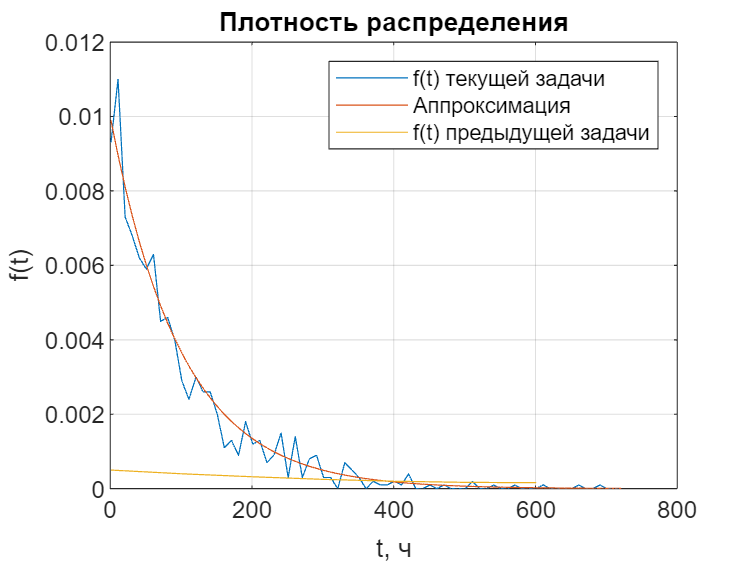

hold on;
plot(t,lambda_app*exp(-lambda_app.*t));
hold on;
plot(t_ex, f_ex);
grid on;
legend('f(t) текущей задачи', 'Аппроксимация', 'f(t) предыдущей задачи');
title('Плотность распределения');
xlabel('t, ч');
ylabel('f(t)');
hold off;

Отдельно построим плотность рапределения предыдущей задачи:

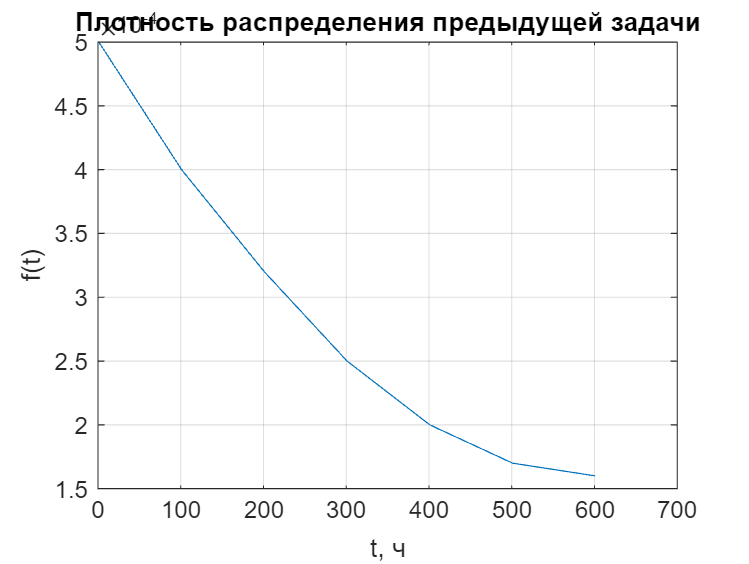

plot(t_ex, f_ex);
grid on;
title('Плотность распределения предыдущей задачи');
xlabel('t, ч');
ylabel('f(t)');
hold off;

Характер у графиков практически одинаковый. В интервале времени 300-500 ч у обоих графиков виден спад. При этом максимумы (амплитуды) различны. 

Я предполагаю, что этому может быть причина, что в первом случае в интервале времени 10 ч количество отказов такого же порядка, как и в интервале 100 ч во втором случае. То есть за счет случайной генерации в нашей текущей задаче за всё время 

max(ksi)

ans = 732.5292

количество отказов равно 

sum(n)

ans = 999

т.е. всей выборке (или практически всей) - N(0), в силу случайности точно сказать нельзя, а во втором случае количество отказов 

sum(n_ex)

ans = 200

меньше N(0).

ВБР $\overset{\wedge }{P} \left(t\right)=\frac{n\left(t\right)}{\textrm{N0}}$:

P = zeros(1, length(n));
R = zeros(1, length(n));
P_ex = zeros(1, length(n_ex));
R_ex = zeros(1, length(n_ex));
R(1) = N;
R_ex(1) = N;
for i = 1:length(n)
    if i ~= length(n)
        R(i+1) = R(i) - n(i);
    end
    P(i) = R(i)/N;
end
for i = 1:length(n_ex)
    if i ~= length(n_ex)
        R_ex(i+1) = R_ex(i) - n_ex(i);
    end
    P_ex(i) = R_ex(i)/N;
end

Аппроксимация аналогичным образом:

error = 10000000;
for lambda = -5:0.01:5
    P_app = exp(-lambda.*t);
    sum_error = 0;
    for i = 1:length(n)
        sum_error = sum_error + abs(P(i) - P_app(i));
    end
    if sum_error < error
        error = sum_error;
        lambda_app = lambda;
    end
end

Построим графики

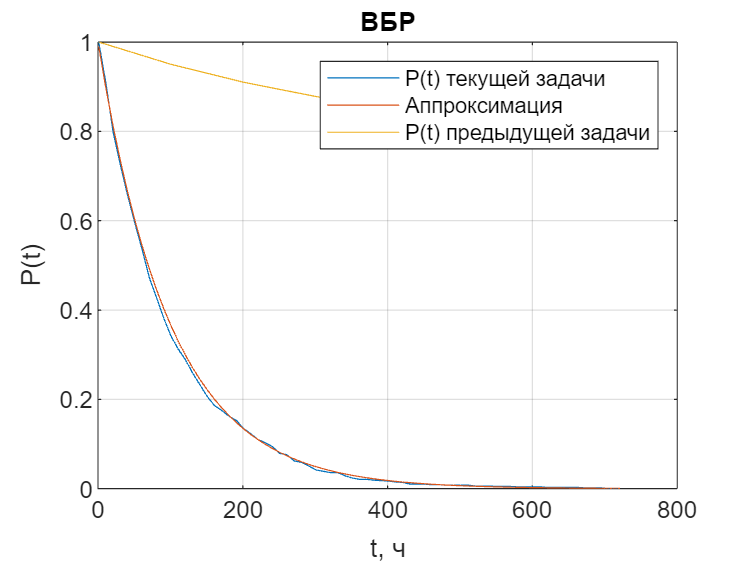

plot(t, P)
hold on;
plot(t, exp(-lambda_app.*t));
hold on;
plot(t_ex, P_ex);
legend('P(t) текущей задачи', 'Аппроксимация', 'P(t) предыдущей задачи');
title('ВБР');
xlabel('t, ч');
ylabel('P(t)');
grid on;
hold off;

Отдельно построим ВБР предыдущей задачи:

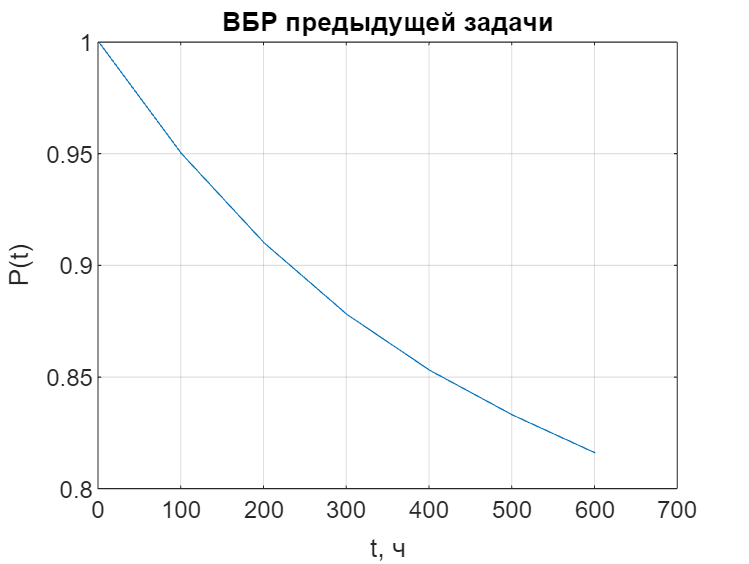

plot(t_ex, P_ex);
grid on;
title('ВБР предыдущей задачи');
xlabel('t, ч');
ylabel('P(t)');
hold off;

ВБР по реальной выборке менее резко убывает. Статистическая оценка ВБР пропорционально зависит от отказов, поэтому причина аналогична предыдущему выводу.

То есть в случайной выборке практически все объекты отказали - мы рассматриваем весь жизненный цикл объектов.

ИО $\overset{\wedge }{\lambda} \left(t\right)=\frac{\Delta n\left(t-\frac{\Delta t}{2};t+\frac{\Delta t}{2}\right)}{\Delta t\bullet N_{\textrm{ср}} \left(t\right)}$ , то есть отношение числа отказов на интервале к произведению длины интервала и среднему знаечнию числа отказов на интервале, где

$N_{\textrm{ср}} \left(t\right)=\frac{N\left(t-\frac{\Delta t}{2}\right)+N\left(t+\frac{\Delta t}{2}\right)}{2}$, где в числителе сумма числа отказов в начале интервала и в конце. 

mod = zeros (1, length(n)); % суммы отказов на интервале (для вычисления Nmid)
Nmid = zeros (1, length(n));
l = zeros (1, length(n));
mod_ex = zeros (1, length(n_ex)); % суммы отказов на интервале (для вычисления Nmid)
Nmid_ex = zeros (1, length(n_ex));
l_ex = zeros (1, length(n_ex));

mod(1) = N - n(1);
Nmid(1) = (N + mod(1))/2;
l(1) = n(1)/(dt*Nmid(1));
for i = 2:length(n)
    mod(i) = mod(i-1) - n(i);
    Nmid(i) = (mod(i-1) + mod(i))/2; 
    l(i) = n(i)/(dt*(Nmid(i)));
end

mod_ex(1) = N - n_ex(1);
Nmid_ex(1) = (N + mod_ex(1))/2;
l_ex(1) = n_ex(1)/(100*Nmid_ex(1));
for i = 2:length(n_ex)
    mod_ex(i) = mod_ex(i-1) - n_ex(i);
    Nmid_ex(i) = (mod_ex(i-1) + mod_ex(i))/2; 
    l_ex(i) = n_ex(i)/(100*(Nmid_ex(i)));
end

plot(t, l);
hold on;

Аппроксимация аналогичным образом:

error = 10000000;
for lambda = -5:0.01:5
    sum_error = 0;
    for i = 1:length(n)
        sum_error = sum_error + abs(l(i) - lambda);
    end
    if sum_error < error
        error = sum_error;
        lambda_app = lambda;
    end
end

Построим графики

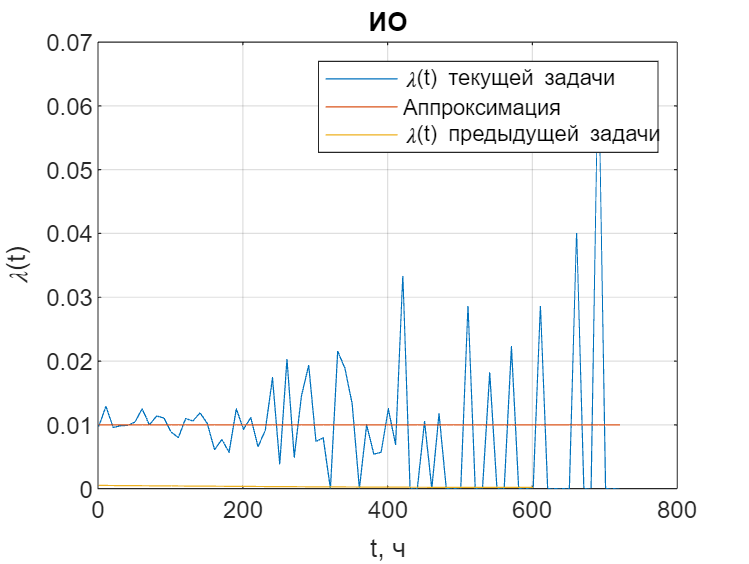

plot(t, lambda_app./t.*t);
hold on;
plot(t_ex, l_ex);
grid on;
hold off;
legend('\lambda(t) текущей задачи', 'Аппроксимация','\lambda(t) предыдущей задачи');
title('ИО');
xlabel('t, ч');
ylabel('\lambda(t)')

Отдельно построим ИО предыдущей задачи:

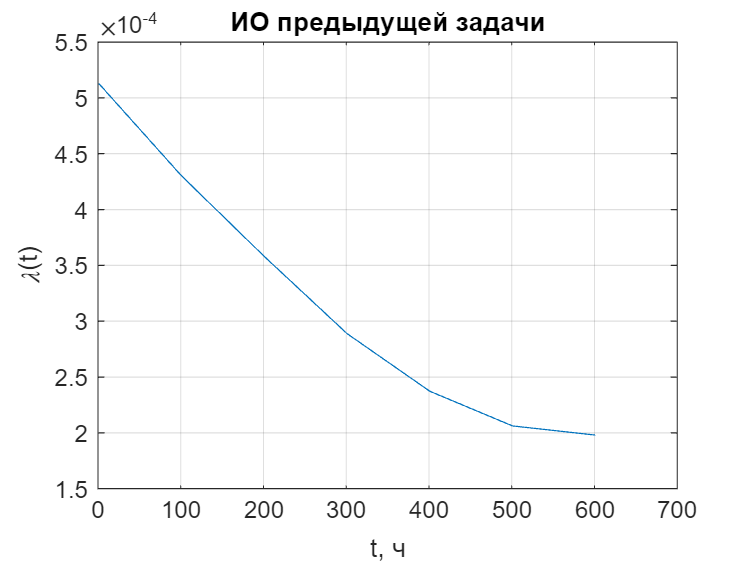

plot(t_ex, l_ex);
grid on;
title('ИО предыдущей задачи');
xlabel('t, ч');
ylabel('\lambda(t)');

По случайной выборке получается так, что погрешность ИО велика, при аппроксимации мы не получаем константы. Погрешность аппоксимированной ИО довольно велика.

Характер ИО реальной выборки говорит о том, что выборка производилась на этапе приработки, возможно, что эта еще одна причина отличия графиков ВБР и плотности распределения. 

pd = fitdist(transpose(n_ex),'exponential')

pd =   ExponentialDistribution

  Exponential distribution
    mu = 28.5714   [15.3146, 71.064]



$$\lambda ~0\ldotp 05\;ч^{-1} \;$$


pd1 = fitdist(transpose(n),'exponential')

pd1 =   ExponentialDistribution

  Exponential distribution
    mu = 13.6849   [11.0177, 17.4588]



$$\lambda ~0\ldotp 01\;ч^{-1} \;$$


К тому же интенсивности отказов у выборок разные. Объекты случайной выборки отказывают чаще реальных.

### **Приложение А**

В алгоритме рассматриваем случайные сгенерированные наработки на интервалах времени dt. Количество интервалов будет вычисляться отношением максимальной сгенерированной наработки и  интервала времени. Далее рассматриваем каждый интервал: (0, dt), (dt, 2*dt) и т.д. И считаем количество наработок них.

Построим распределение отказов для интервала 10 и 100 ч:

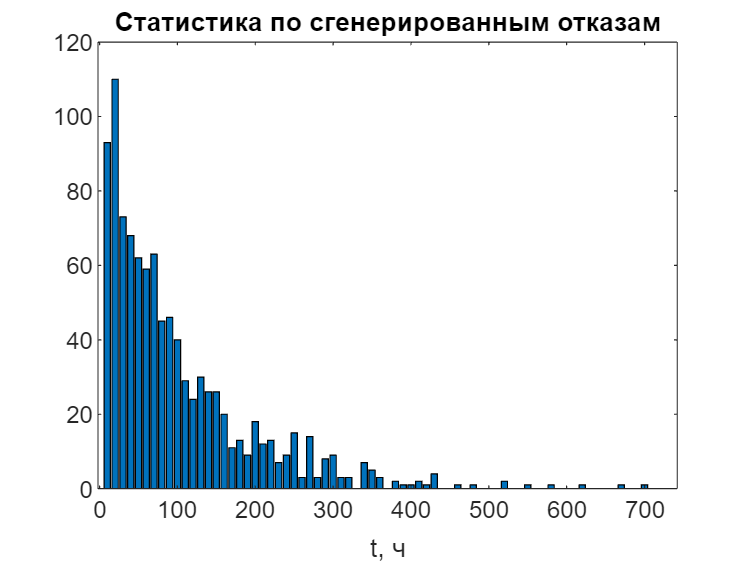

bar((1:length(n))*dt, n);
title('Статистика по сгенерированным отказам');
xlabel('t, ч');

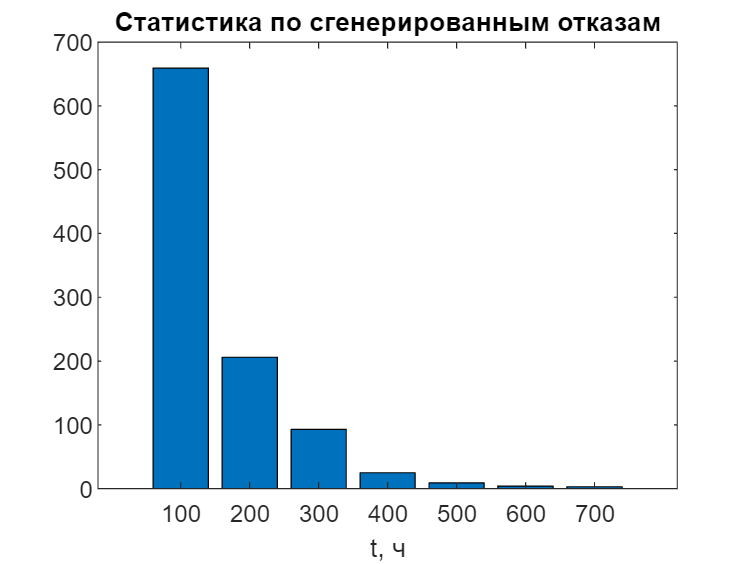

dt = 100;
n = zeros(1, round(max_ksi/dt));
interval = 0;
for i = 1:length(n)
    for j = 1:length(ksi)
        if and((ksi(j) > interval), (ksi(j) < interval + dt))
            n(i) = n(i) + 1;
        end
    end
    interval = interval + dt;
end
bar((1:length(n))*dt, n);
title('Статистика по сгенерированным отказам');
xlabel('t, ч');

Построим гистограмму по отказам по предыдущей задаче:

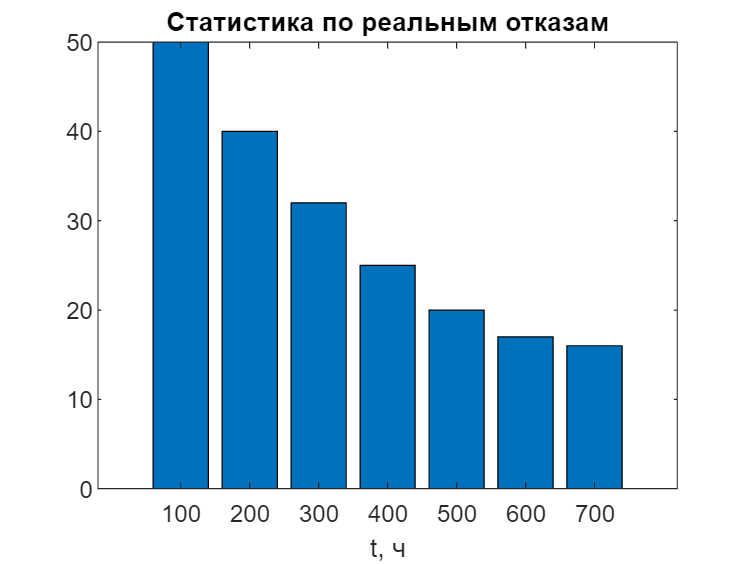

number_int = length(n);
bar((1:number_int)*dt, n_ex(1:number_int));
title('Статистика по реальным отказам');
xlabel('t, ч');

### **Приложение Б**

Метод состоит в нахождении оптимального параметра $\lambda$ суммировнием ошибки (погрешности), которая на каждой иттерации является разностью абсолютного и реального значения в известных точках. Искомое $\lambda$ соответствует случаю, когда ошибка минимальна.

Для подтверждения результата суммарную ошибку задаем матрицей. В левом столбце величина ошибки, в правом $\lambda$ (значения отстортированы по параметрe:

- 0.015	0.01

- 0.0536	0.02

- 0.0844	0.03

- 0.0906	6.55

- 0.0906	6.54

- 0.0907	6.56

- 0.0907	6.53

- 0.0908	6.57

- 0.0908	6.52

Как видно из приведенных данных при  $\lambda$ = 0.01 ошибка минимальна. 

Пределы варьирования $\lambda$ можно менять как и шаг (при задании шага 0.001 искомым значением также являлось 0.01).

Для достоверности результата необходимо провести две или даже три процедуры аппроксимации с разными шагами и проверить результаты.